# P06: Convolución y correlación

## Integrantes:

Patiño Rivero Francisco

Salinas Landa Elías Omar

### Introducción

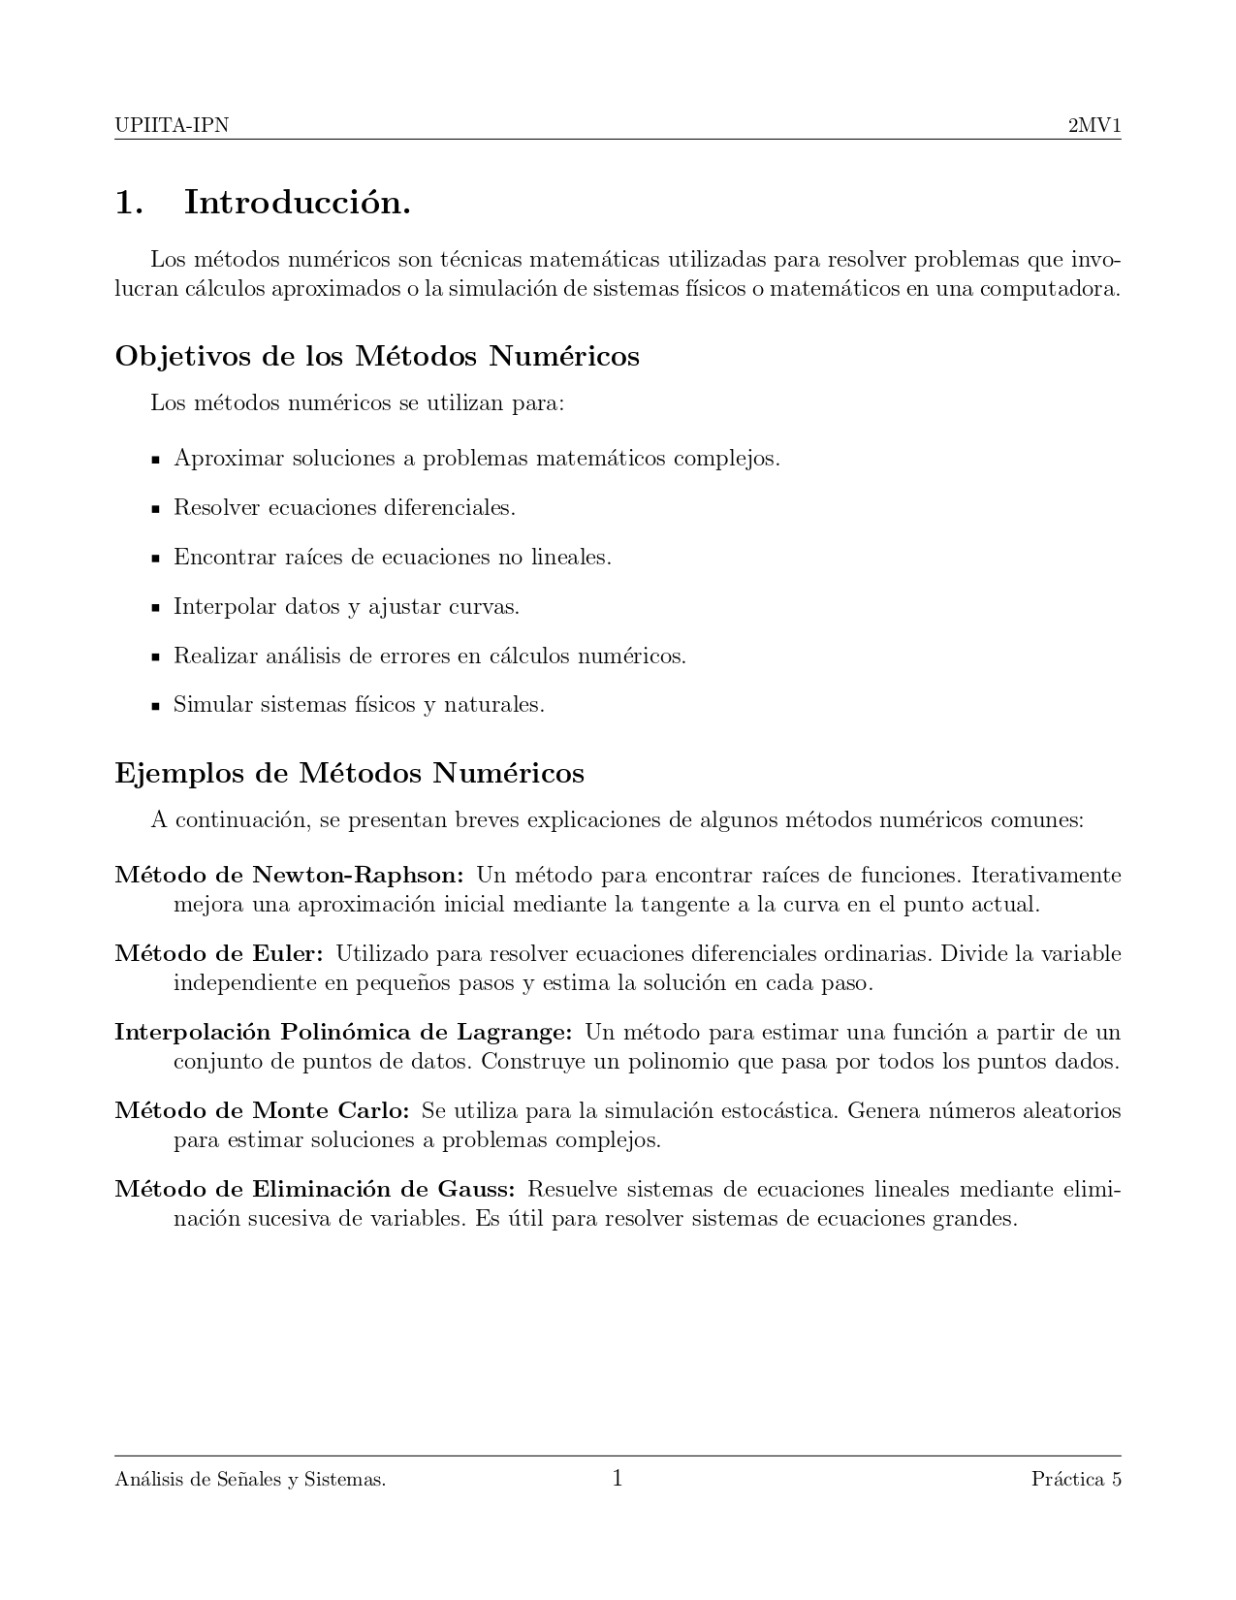

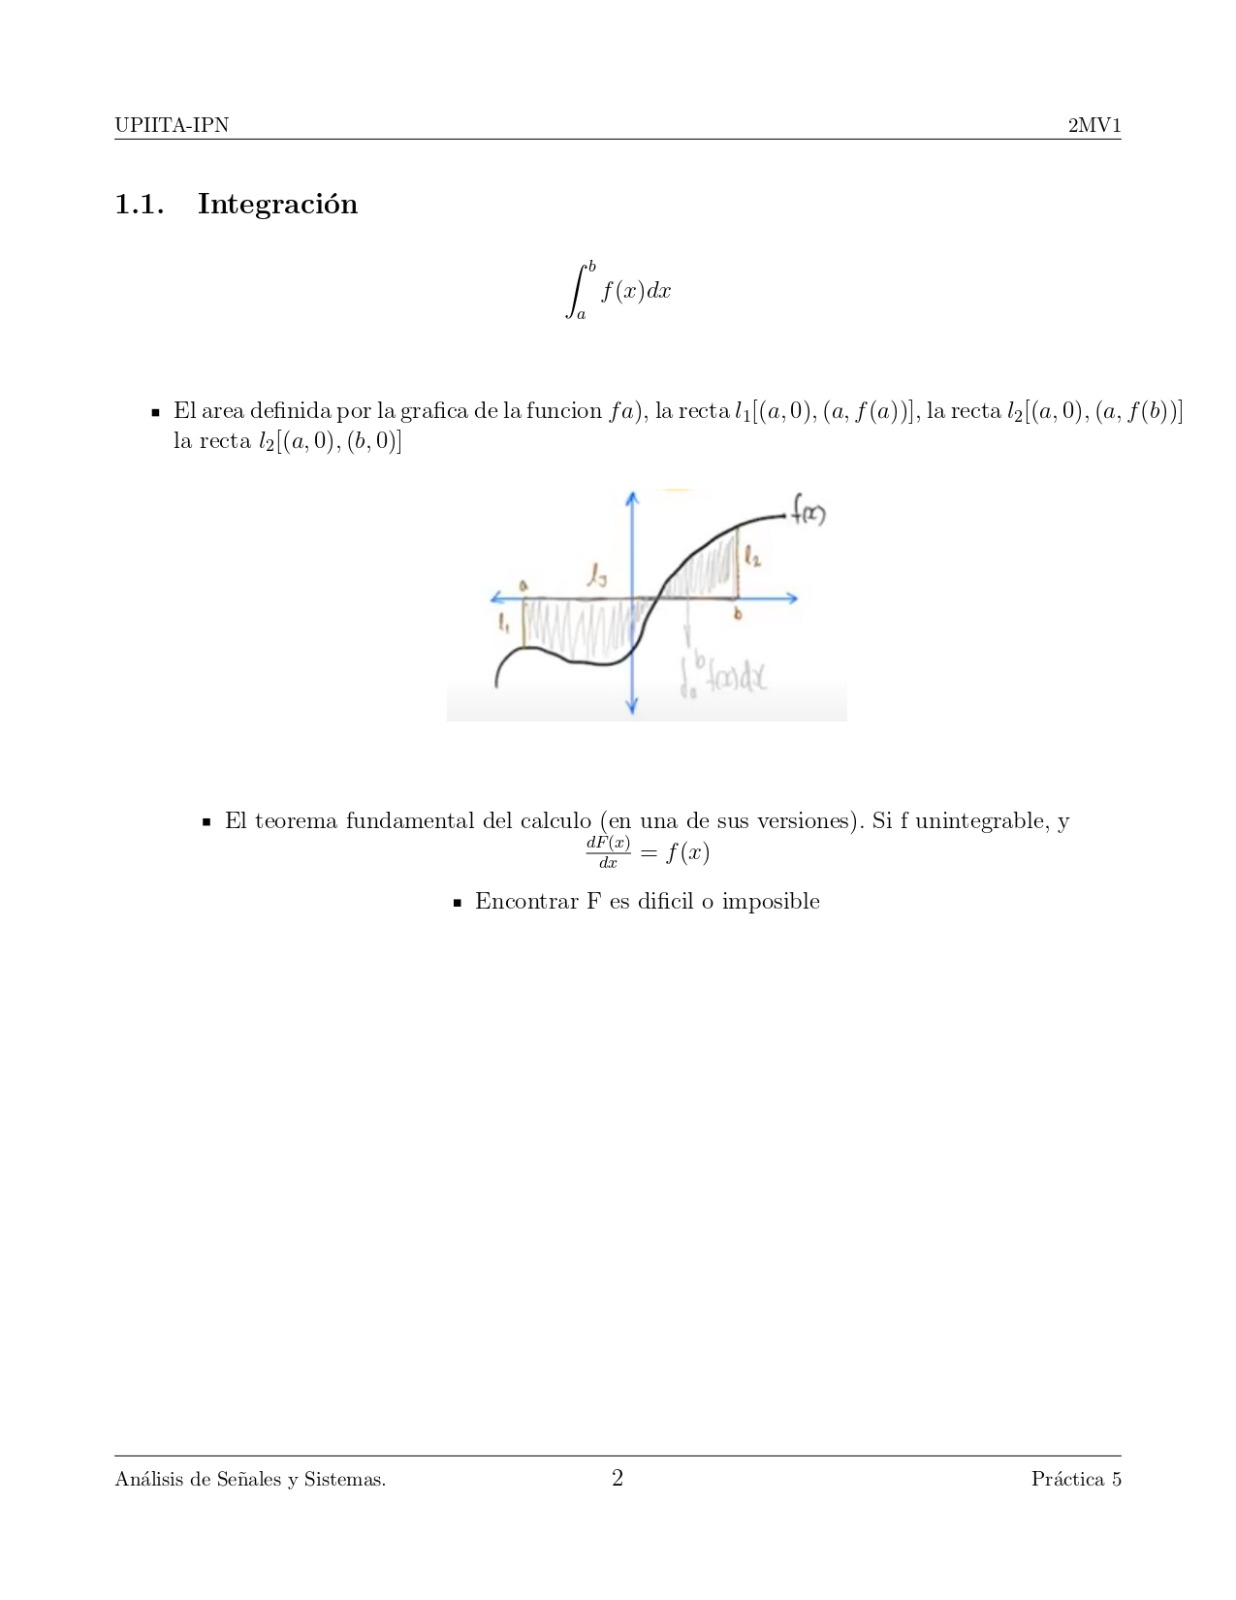

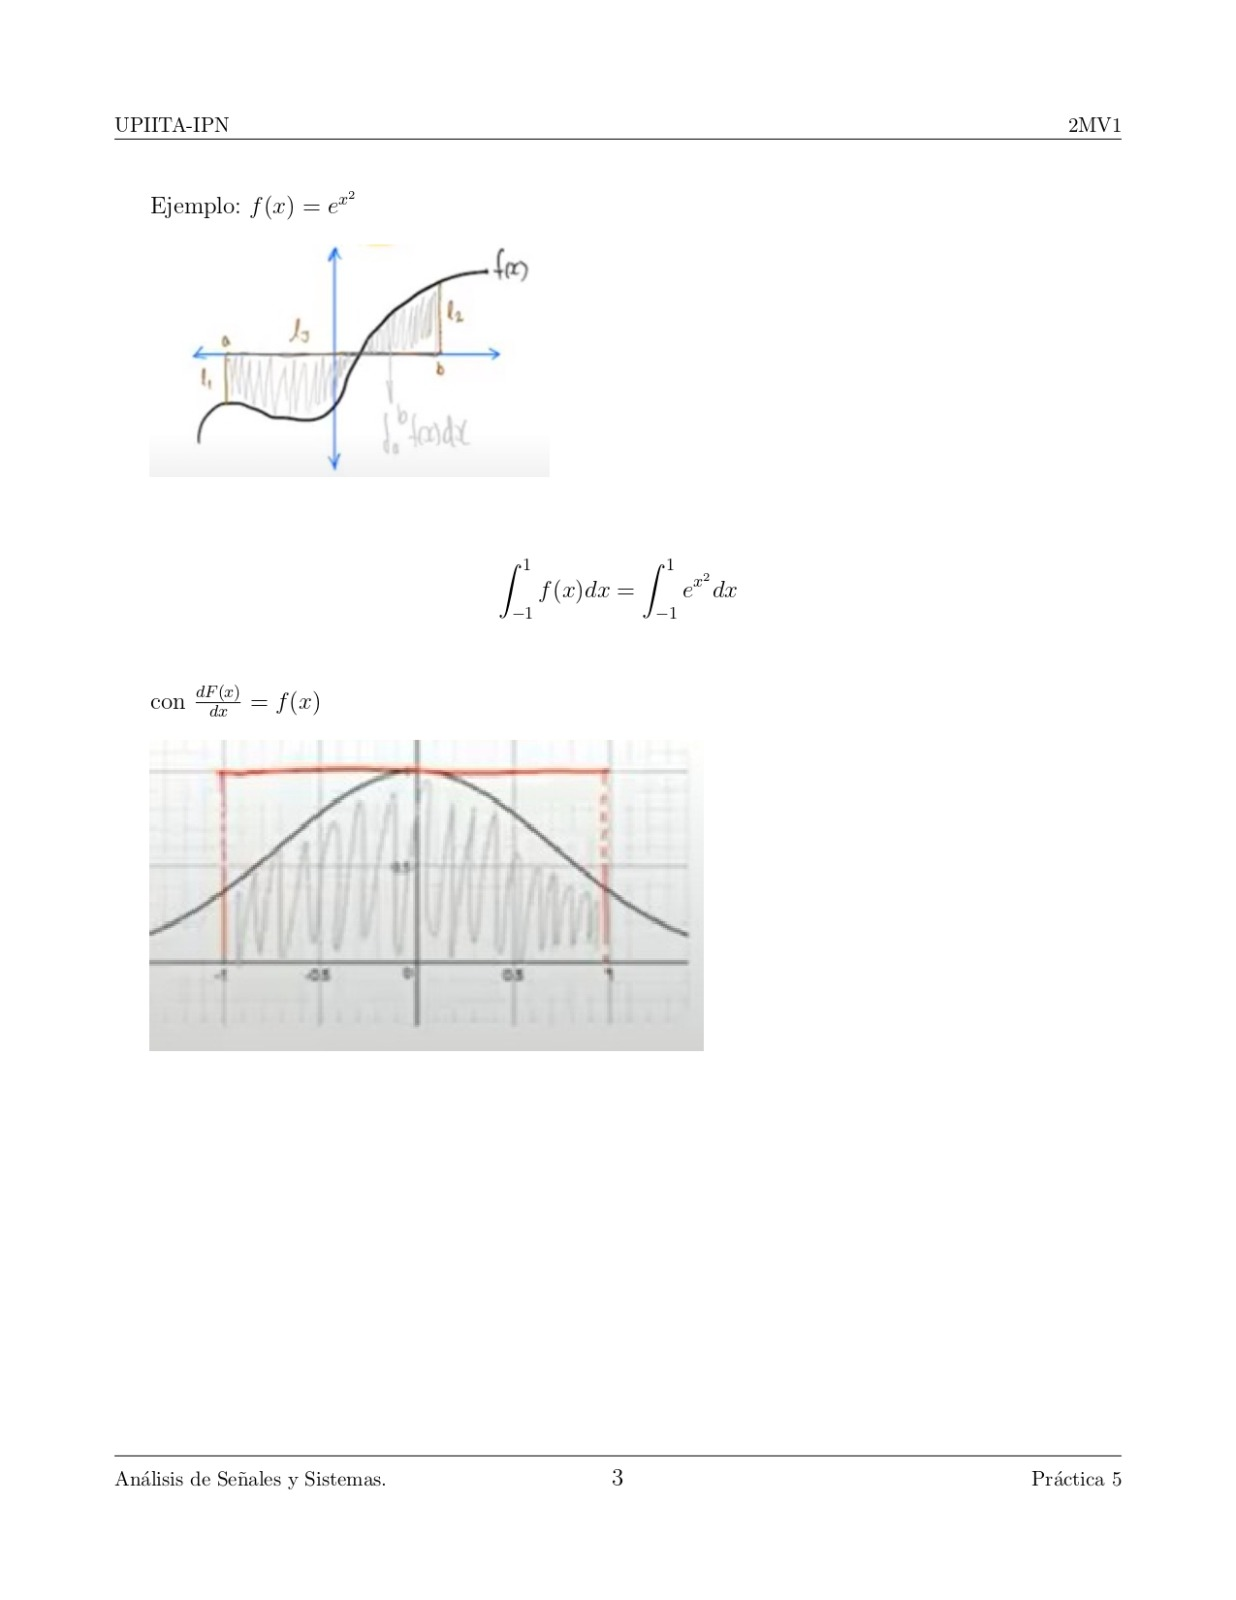

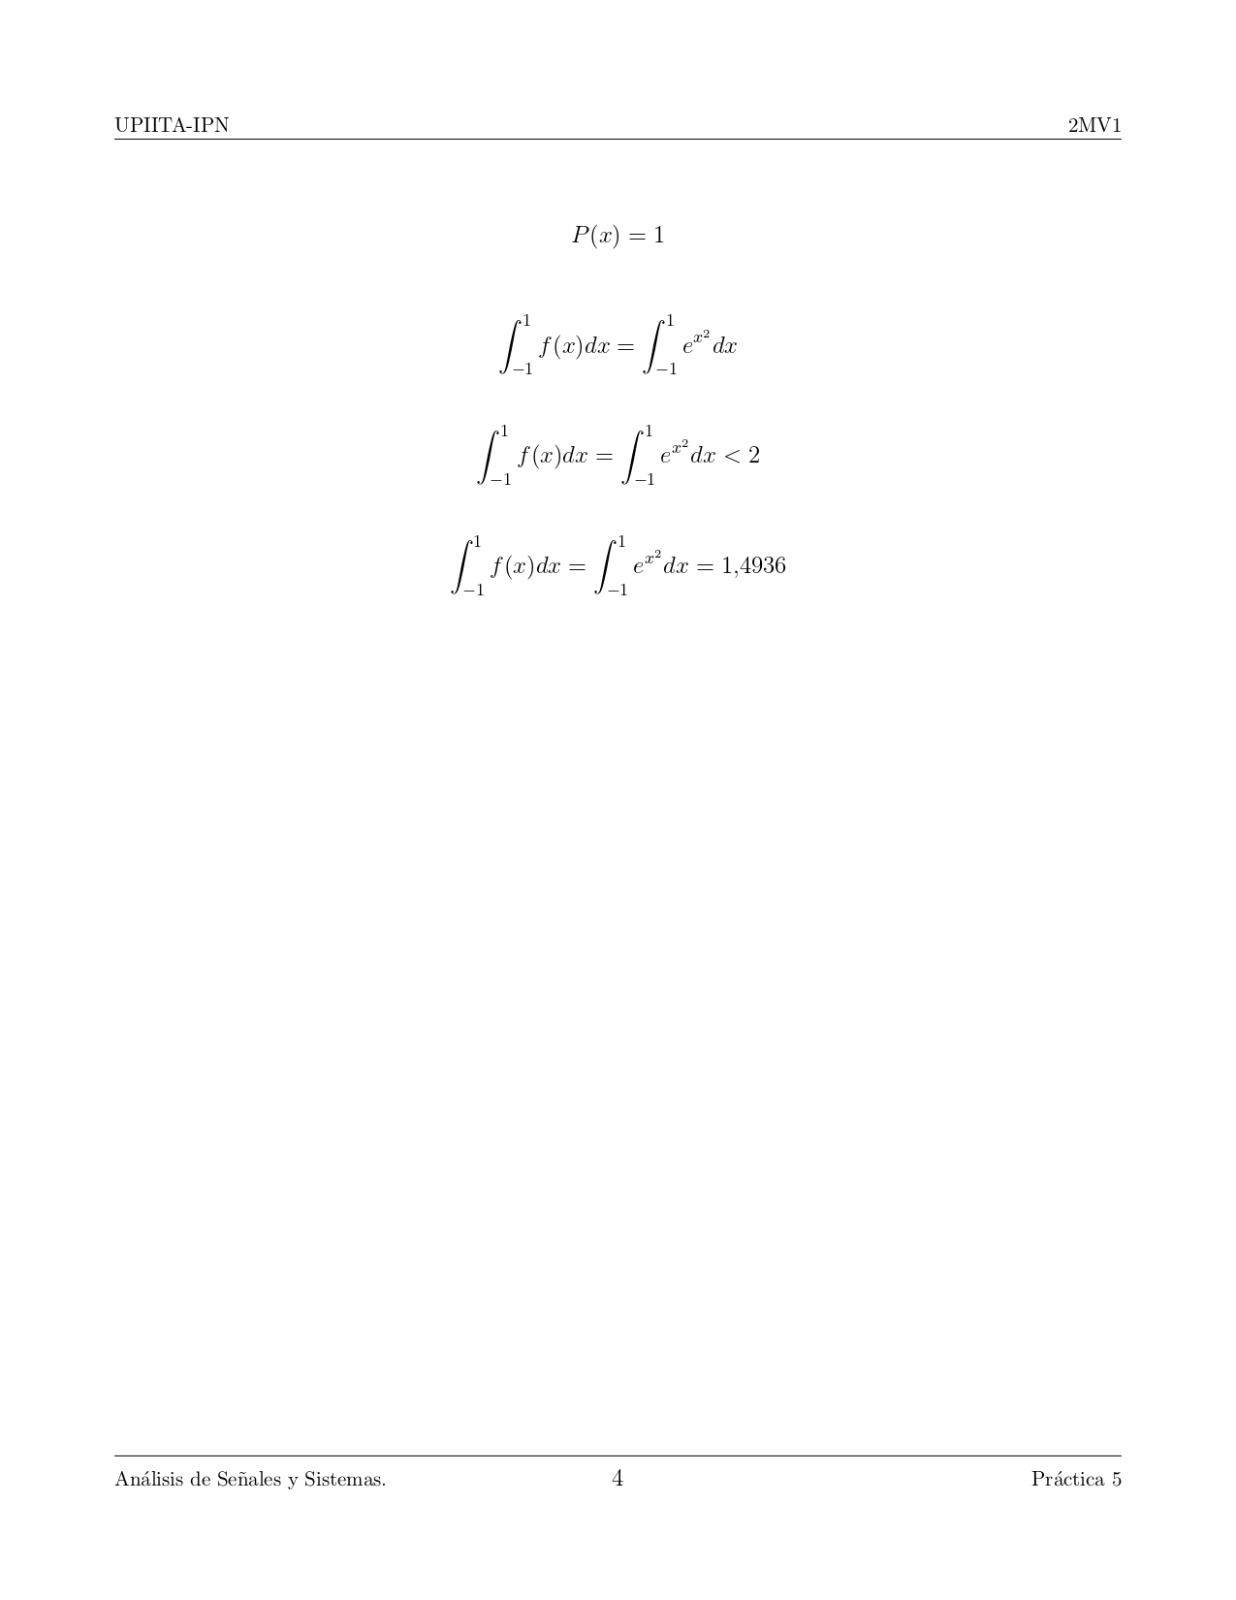

### Desarrollo

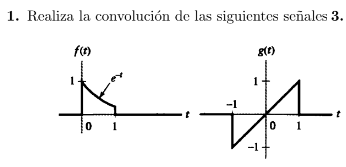

figure
subplot(1,3,1)
syms t
x=piecewise(t<0,0,0<t<1,1.5*sin(pi*t),t>1,0);
fplot(x,[-0.25,1.25],'r')
grid on
title('x(t)')
axis([-1 3.6 -2 2]);
subplot(1,3,2)
h=piecewise(t<0,0,0<t<1,1.5,1<t<2,0,2<t<2.5,-1.5,t>2.5,0);
fplot(h,[-0.25,2.75],'r')
grid on
title('h(t)')
axis([-1 3.6 -2 2]);
t1=0:0.01:1;
t2=1:0.01:2;
t3=2:0.01:2.5;
t4=2.5:0.01:3;
t5=3:0.01:3.5;
subplot(1,3,3)
plot(t1,(1.5^2/pi)*(1-cos(pi*t1)))
hold on
plot(t2,(1.5^2/pi)*(1-cos(pi*t2)))
plot(t3,(1.5/pi)*(cos(pi*t3)-1))
plot(t4,(1.5/pi)*(cos(pi*t4)-sin(pi*t4)))
plot(t5, (-1.5/pi)*(1+sin(pi*t5)))
grid on
title('x(t)*h(t)')
axis([-1 3.6 -2 2]);